# Load matalab vehicle dataset from vision toolbox

imageDir = fullfile(matlabroot,'toolbox','vision','visiondata','vehicles');
addpath(imageDir);
data = load('vehicleTrainingData.mat');
vehicleDataset = data.vehicleTrainingData;

# Check the vehicle images that are available

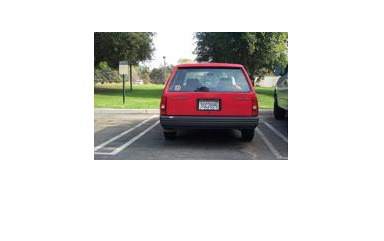

%img = imread('vehicles/image_00103.jpg'); %img 4
%img = imread('vehicles/image_00143.jpg'); %img 3
%img = imread('vehicles/image_00003.jpg'); %img 2 
img = imread('vehicles/image_00245.jpg'); %img 1
imshow(img);

imwrite(img,'ex_1.png');

# Shuffle thet training dataset and split to training (80%) and testing (20%) sets 

rng(0);
shuffledIdx = randperm(height(vehicleDataset));
idx = floor(0.8 * height(vehicleDataset));
trainingDataTbl = vehicleDataset(shuffledIdx(1:idx),:);
testDataTbl = vehicleDataset(shuffledIdx(idx+1:end),:);

%create training and testing datastorees 
imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'vehicle'));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'vehicle'));

%Combine the datastores
trainingData = combine(imdsTrain,bldsTrain);
testData = combine(imdsTest,bldsTest);

# Load the pretrained YOLO v2 model, set parameters and train

net = load('yolov2VehicleDetector.mat');
lgraph = net.lgraph

lgraph =   LayerGraph with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
    Connections: [24×2 table]
     InputNames: {'input'}
    OutputNames: {'yolov2OutputLayer'}



%set the training parameters
options = trainingOptions('sgdm',...
          'InitialLearnRate',0.001,...
          'Verbose',true,...
          'MiniBatchSize',16,...
          'MaxEpochs',30,...
          'Shuffle','never',...
          'VerboseFrequency',30,...
          'CheckpointPath',tempdir);

%train the detector 
[detector,info] = trainYOLOv2ObjectDetector(trainingData,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* vehicle

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |         7.13 |         50.8 |          0.0010 |
|       3 |          30 |       00:00:07 |         1.41 |          2.0 |          0.0010 |
|       5 |          60 |       00:00:15 |         0.88 |          0.8 |          0.0010 |
|       7 |          90 |       00:00:26 |         0.73 |          0.5 |          0.0010 |
|       9 |         120 |       00:00:31 |         0.65 |          0.4 |          0.0010 |
| 

# Evaluation 

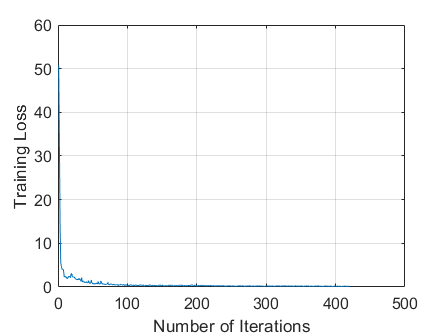

%training loss plot
figure; 
plot(info.TrainingLoss)
grid on
xlabel('Number of Iterations')
ylabel('Training Loss')
saveas(gcf,"training_loss.png");

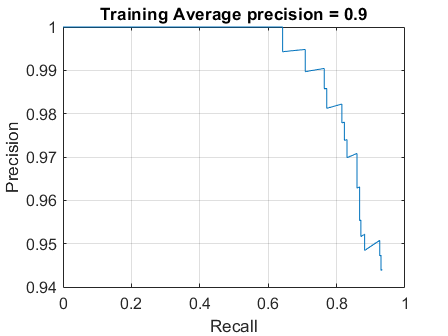

%evaluation on the training data 
results = detect(detector, trainingData);
[ap, recall, precision] = evaluateDetectionPrecision(results, bldsTrain);

figure;
plot(recall, precision);
grid on
title(sprintf('Training Average precision = %.1f', ap))
xlabel('Recall');
ylabel('Precision');
saveas(gcf,"training_evaluation.png");

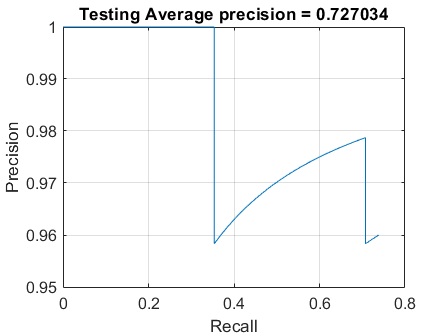

%evaluation on the testing data 
results = detect(detector, testData);
[ap, recall, precision] = evaluateDetectionPrecision(results, bldsTest);

figure;
plot(recall, precision);
grid on
title(sprintf('Testing Average precision = %.6f', ap))
xlabel('Recall');
ylabel('Precision');
saveas(gcf,"testing_evaluation.png");

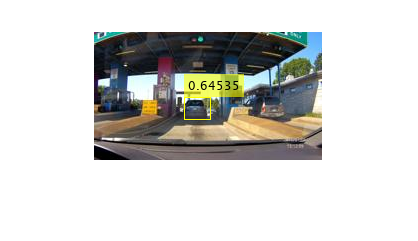

img = imread('vehicles/image_00023.jpg'); %images from the testing set
[bboxes,scores] = detect(detector,img);
if(~isempty(bboxes))
    img = insertObjectAnnotation(img,'rectangle',bboxes,scores);
end
figure
imshow(img)

imwrite(img,'result_4.png');

# References

%https://www.mathworks.com/help/vision/ug/train-yolo-v2-network-for-vehicle-detection.html
%https://www.mathworks.com/help/vision/ref/evaluatedetectionprecision.html